## Introduction to **Bio-Informatics** 2022

# **Assignment 5: **Gene expression data 

**Chiara Paglioni (i6249782)**

Some toxicology researchers want to know the effect of Cyclosporin A (CSA) on human cells. They take two doses of this compound (20uM and 3uM) and take samples after 12, 24, 48 and 72 hours of exposure. They also take samples from cells exposed to just the solvent which the CSA is normally dissolved into, DMSO (eg the samples labelled DMSO are untreated and the samples labelled CSA are treated). They want to know which genes are affected by the CSA.  

- After preprocessing pick at least one dose/timepoint combination and find the differentially expressed genes.

The data for this task is in the file raw_data_labelled.csv the rows are labelled with the affymetrix id of the probe - there will be many probes measuring each gene.  

**Read data**

clear;
data = readtable('raw_data_labelled.csv')

data = 54675×37 table
          Var1          DMSO_12h_1    CsA_20uM_12h_1    CsA_3uM_12h_1    DMSO_24h_1    CsA_20uM_24h_1    CsA_3uM_24h_1    DMSO_48h_1    CsA_20uM_48h_1    CsA_3uM_48h_1    DMSO_72h_1    CsA_20uM_72h_1    CsA_3uM_72h_1    DMSO_12h_2    CsA_20uM_12h_2    CsA_3uM_12h_2    DMSO_24h_2    CsA_20uM_24h_2    CsA_3uM_24h_2    DMSO_48h_2    CsA_20uM_48h_2    CsA_3uM_48h_2    DMSO_72h_2    CsA_20uM_72h_2    CsA_3uM_72h_2    DMSO_12h_3    CsA_20uM_12h_3    CsA_3uM_12h_3    DMSO_24h_3    

**Plot data and Preprocessing**

First of all, the given values are log transformed. To do so, the log base 2 of each value of the previous table is computed and saved into a new array: log_data.

% Log transform (log base 2) the data
log_data = table2array(data(1:54675, 2:37));
for i = 1 : length(log_data(:,1))
    for j = 1 : length(log_data(1,:))
        log_data(i, j) = log2(log_data(i, j));
    end
end    
log_data

log_data =    10.1954    9.4686    9.6357   10.0375    9.9174    9.7013    9.2503    9.7288    9.6961    9.4543   10.1344    9.4656    9.9315    9.9069    9.8289    9.3772    9.7912    9.8345    9.5736   10.2986    9.9359    9.4126    9.7515    9.5018   10.0828    8.9986    9.7313    9.8057    9.6366    9.6448    9.5755    9.7557    9.7465    9.3696    9.8549    8.9873
    9.6055    7.9858    8.8424    9.0224    8.0417    8.6202    7.6900    7.5196    7.7211    7.4512    8.1472    7.7944    9.3945    8.2384    8.9844    8.6092    8.1137    8.5216    8.2644    8.4388    8.1033    7.9039    7.8549    7.8138    9.0620    7.8918    9.1749    8.9830    7.9600    8.8392    8.2095    7.9337    8.2384    7.7582    7.7074    7.5699
    7.4094    6.7879    6.4757    7.2288    7.6795    6.8704    6.8765    7.6724    6.8138    6.7074    7.9658    6.8580    7.0279    7.0607    6.9129    6.9307    8.2946    6.9887    6.9189    8.4512    7.2527    7.1649    7.7448    6.9009    6.9425    6.6366    7.1

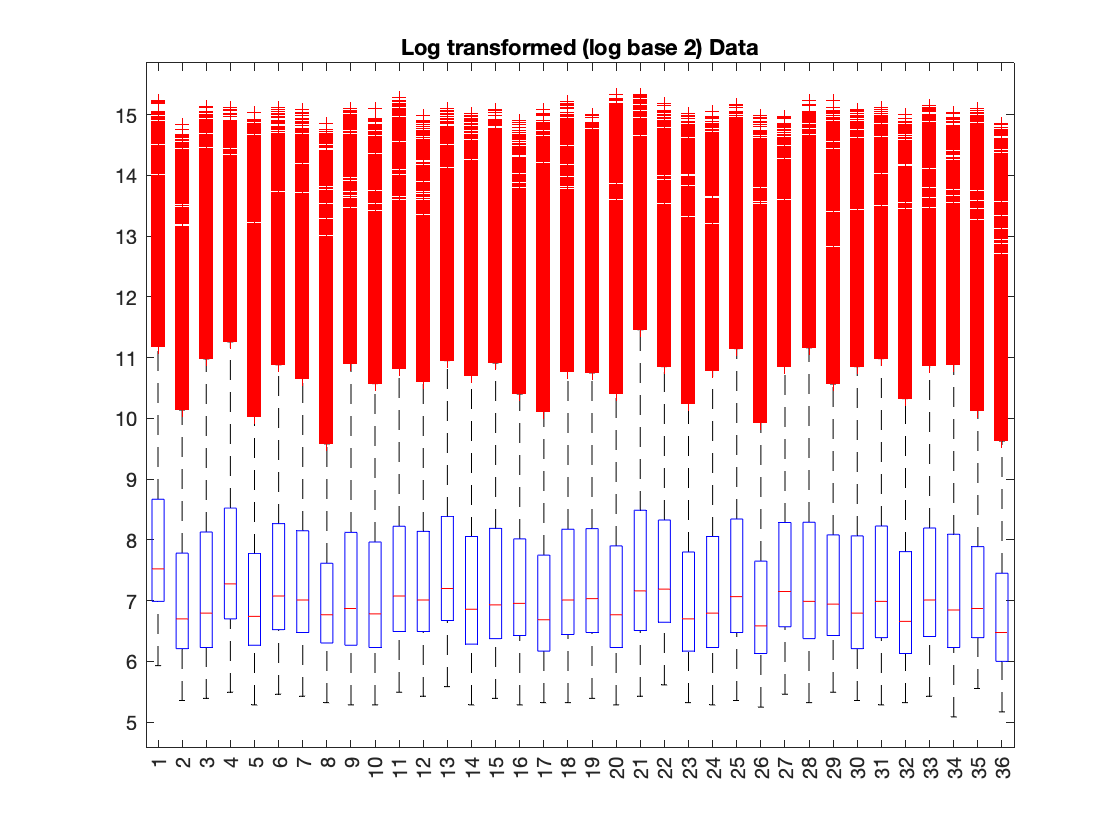

% Boxplot of log transformed data before normalisation
figure;
boxplot(log_data)
title('Log transformed (log base 2) Data')

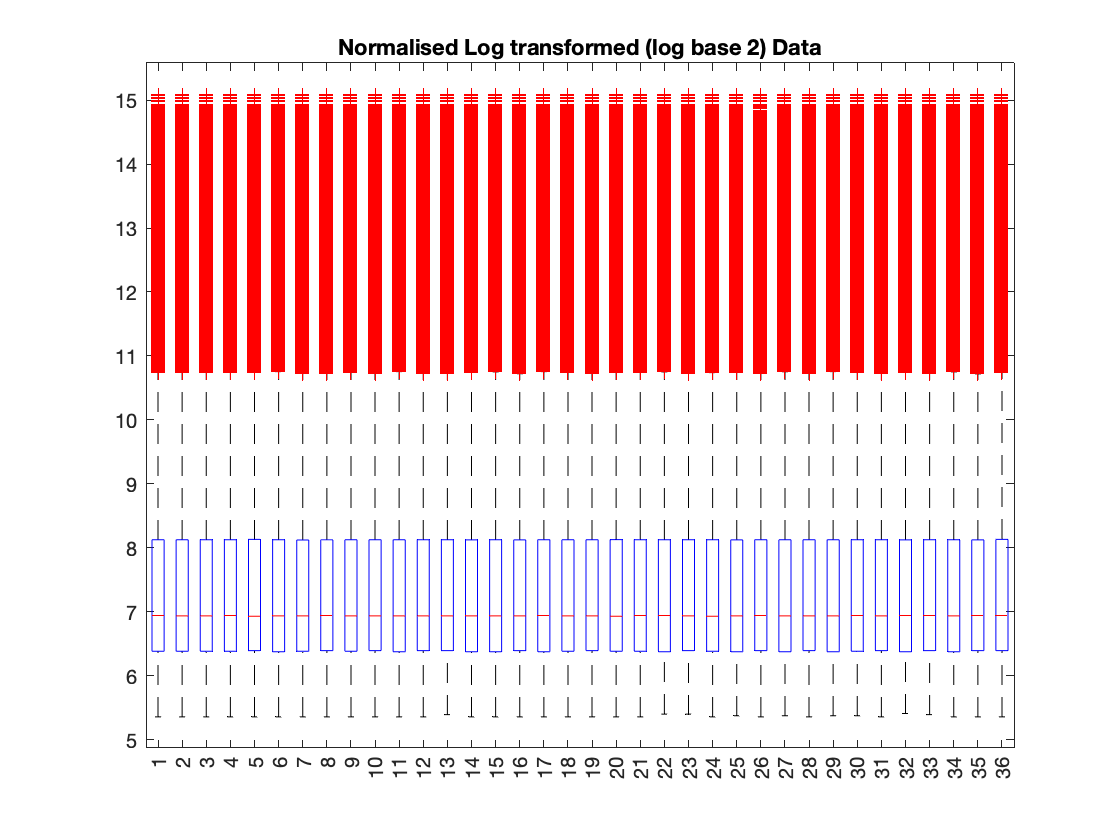

% Data is normalised through quantile normalisation 
% The median of the ranked values is taken instead of the mean
normalised_logData = quantilenorm(log_data, 'Median', true);

% Boxplot of log transformed data after normalisation
figure; 
boxplot(normalised_logData)
title('Normalised Log transformed (log base 2) Data')

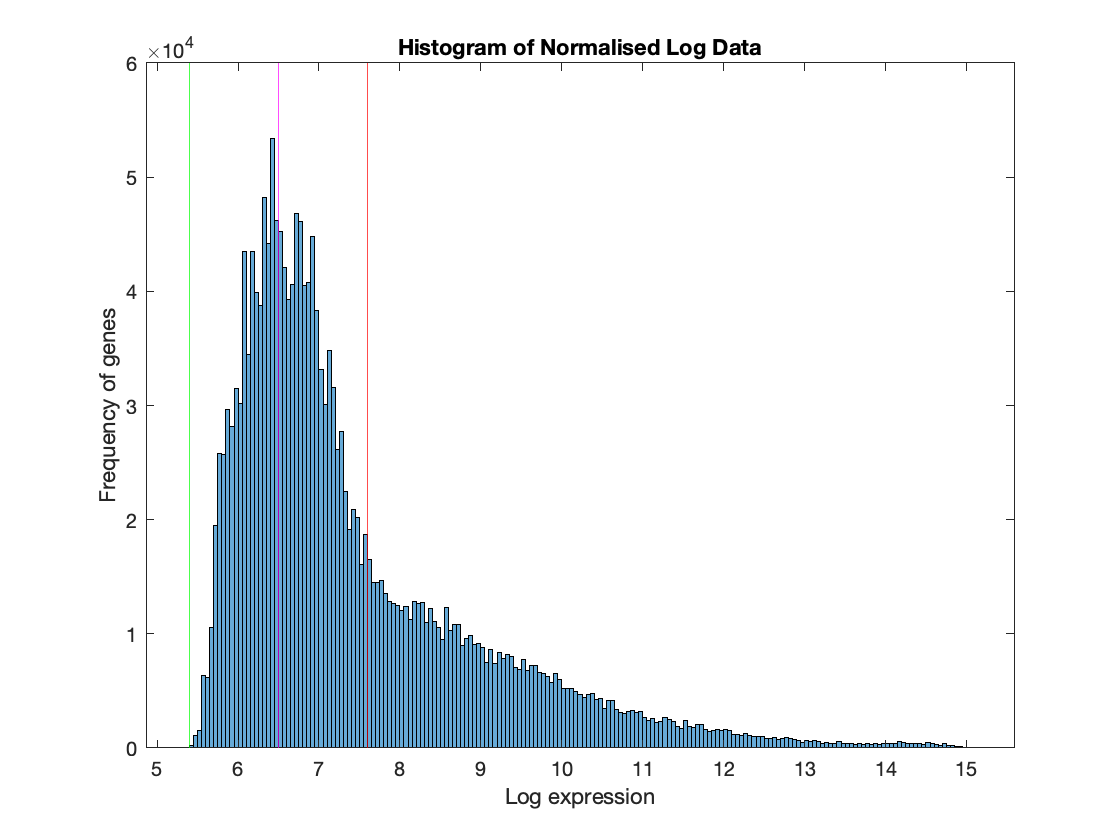

% The cutuff is estimated by observing the histogram
cutOff = 7.6;
% Histogram of normalised data
figure; 
histogram(normalised_logData)
xline(5.4, 'Color', 'Green')
xline(6.5, 'Color', 'Magenta')
xline(cutOff, 'Color', 'Red') 
title('Histogram of Normalised Log Data')
xlabel('Log expression')
ylabel('Frequency of genes')

The histgram shows the data after being log transformed and normalised. Two different distributions appear in this plot: 

- Gaussian distribution: represents the unexpressed genes, giving a background noise signal. 

- Lognormal distribution: represents the expressed genes giving real signal.

The data that belongs to the Gaussian distribution is not relevant thus, a cutoff is selected to filter unexpressed genes from the dataset. In this case, the cutoff is estimated as follows: 

- Start of Gaussian distribution (Green Line): 5.4

- Middle of Gaussian distribution (Pink Line): 6.5

- End of Gaussian distribution (Red Line): 7.6 = 6.5 + 1.1

Now, after preprocessing the data two different dose/timepoint combinations are studied. First, the differentially expressed genes are found. Then, the results of the two combinations are compared. In order for the results to be relevant, the two combinations need to be synchronized. The following are the chosen ones: 

- 1st combination: DMSO at 12h and CSA (20uM) at 12h

- 2nd combination: DMSO at 72h and CSA (20uM) at 72h

**1st combination: DMSO at 12h and CSA (20uM) at 12h**

First, the corresponding columns are retrieved from the previously normalised log data.

dmso_12 = [normalised_logData(:, 2), normalised_logData(:, 14), normalised_logData(:, 26)];
csa_12 = [normalised_logData(:, 3), normalised_logData(:, 15), normalised_logData(:, 27)];

Next, the expressed genes are counted and retrieved. A gene is expressed whenever it is expressed both in the dmso sample and the csa sample. Moreover, to be expressed, a gene needs to be in the Lognormal distribution, i.e. greater than the cufoff.

After checking this conditions, 175997 genes turns out to be expressed.

% Count and retrieve the expressed genes
expressed_count = 0; 
length_data = length(log_data(:,1));
expressed_genes_index = zeros(1, length_data);

for i = 1 : length_data

    expressed_dmso = false;
    expressed_csa = false; 

    if (dmso_12(i, 1) >= cutOff && dmso_12(i, 2) >= cutOff && dmso_12(i, 3) >= cutOff)
       expressed_dmso = true;
    end  

    if (csa_12(i, 1) >= cutOff && csa_12(i, 2) >= cutOff && csa_12(i, 3) >= cutOff)
        expressed_csa = true;
    end 

    if (expressed_dmso || expressed_csa)
        expressed_count = expressed_count + 1; 
        expressed_genes_index(expressed_count) = i;
    end    
end     
expressed_count

expressed_count = 17597

% Indeces of the expressed genes 
expressed_index = nonzeros(expressed_genes_index)'

expressed_index =      1     2     4    12    14    15    19    24    27    29    31    34    37    39    44    46    47    49    50    51    64    65    73    81    82    90   103   118   126   151   152   153   161   162   181   223   248   249   250   251   252   254   255   256   257   258   259   261   263   264


% Merged data of the two samples in a signle matrix
index_samples = [2, 14, 26, 3, 15, 27];
expressed = normalised_logData(expressed_index, index_samples)

expressed =     9.7830    9.8353    9.4051    9.5314    9.6830    9.5878
    8.3332    8.2969    8.3663    8.7748    8.8734    9.0112
    8.6456    8.6339    8.6635    8.8265    8.9915    8.8750
    8.6917    8.8321    8.8408    8.4051    8.3663    8.4553
   10.3077   10.4146   10.0130   10.6402   10.5134   10.2825
    9.0375    8.9144    9.1098    9.0815    9.1006    9.0620
    9.1344    8.8517    8.1997    8.4367    8.4828    8.6402
    8.1319    8.0980    8.0795    7.6330    7.7780    7.3083
    9.9585   10.1189    9.5372    9.1267    9.0000    9.0580
    7.9366    7.6900    7.8494    7.9658    8.1163    8.2761


Now, to find which of the expressed genes are differentially expressed the two samples are compared to find the fold change and ttest p-value.

First, the log (base 2) fold change for each expressed gene is calculated.  The values are log base 2, so the fold change will be calculated with subtraction. Moreover, the weakest compound (DMSO) is subtracted from the stronger one (CSA 20uM).

dmso_exp = expressed(:, 1:3);
csa_exp = expressed(:, 4:6);
foldchanges = zeros(1, expressed_count);
for i = 1 : expressed_count
    foldchanges(1, i) = mean(csa_exp(i, :)) - mean(dmso_exp(i, :));
end
foldchanges

foldchanges =    -0.0738    0.5543    0.2500   -0.3793    0.2336    0.0608   -0.2087   -0.5300   -0.8100    0.2941   -0.0218   -0.1889    0.8622    0.1179    0.2788    0.5573    0.9925    0.4610   -0.1768   -0.1134   -0.2717    0.0176    0.1919    1.0762   -0.5423   -0.4200   -0.1574    0.0221   -0.0379   -1.0247    0.2742    0.6310   -0.1106    0.3003   -0.0264   -0.1302   -0.4486   -0.5722   -0.1031    0.0139    0.0341   -0.0850   -0.3300    0.7216   -0.1081    0.1439    0.0758   -0.4705   -0.5375   -0.5939


Next, a ttest is performed to compare the two samples and calculate the p-values. Moreover, a muliple testing correction is applied to the previous p-values. The is achieved through the **mafdr **function with the BHFDR flag to perform the Benjamini-Hochberg procedure.

[h, p] = ttest2(dmso_exp', csa_exp')

h =      0     1     1     1     0     0     0     1     1     0     0     0     1     0     1     1     1     0     0     0     0     0     0     1     1     1     0     0     0     1     0     1     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     1


p =     0.6322    0.0015    0.0073    0.0023    0.2165    0.3546    0.5025    0.0192    0.0103    0.0629    0.8691    0.0948    0.0002    0.2951    0.0489    0.0057    0.0041    0.1117    0.0918    0.6626    0.2287    0.8487    0.0824    0.0040    0.0307    0.0258    0.0757    0.8874    0.6902    0.0001    0.1567    0.0006    0.4395    0.2827    0.8753    0.6317    0.1809    0.0468    0.6706    0.9516    0.7489    0.0962    0.0704    0.0897    0.4426    0.0816    0.5608    0.0593    0.0804    0.0017


adjusted_p = mafdr(p, 'BHFDR', 'true')

adjusted_p =     0.7162    0.0158    0.0334    0.0185    0.3196    0.4639    0.6041    0.0587    0.0404    0.1297    0.9064    0.1735    0.0087    0.4029    0.1087    0.0292    0.0246    0.1957    0.1694    0.7418    0.3325    0.8910    0.1567    0.0244    0.0799    0.0712    0.1479    0.9197    0.7644    0.0063    0.2509    0.0114    0.5461    0.3901    0.9109    0.7160    0.2793    0.1056    0.7485    0.9673    0.8127    0.1752    0.1405    0.1666    0.5487    0.1556    0.6552    0.1242    0.1540    0.0166


Finally, to asnwer the research question, the upregulated and downregulated genes are counted. These are the genes of human cells that have been affected by Cyclosporin A (CSA). The following constratins apply: 

- Upregulated genes: log base 2 fold change >1 if upregulated 

- Downregulated genes: log base 2 fold change < -1 if downregulated

Moreover, to increase the precision of the results, only the genes with an adjusted p-value lower than 0.05 are counted.

In the end, there are: 

- Upregulated genes: 462

- Downregulated genes: 376

- Total human genes affected by CSA: 838

count_upregulated = 0;
count_downregulated = 0; 
for i = 1 : length(foldchanges)
    if adjusted_p(i) < 0.05
        if foldchanges(i) > 1
            count_upregulated = count_upregulated + 1;

        end

        if foldchanges(i) < -1
            count_downregulated = count_downregulated + 1;
        end
    end    
end
count_upregulated

count_upregulated = 462

count_downregulated

count_downregulated = 376

**2nd combination: DMSO at 72h and CSA (20uM) at 72h**

Repeat expriment with 2nd combination to draw a conclusion and compare it with the previous one.

First, the corresponding columns are retrieved from the previously normalised log data.

dmso_72 = [normalised_logData(:, 11), normalised_logData(:, 23), normalised_logData(:, 35)];
csa20_72 = [normalised_logData(:, 12), normalised_logData(:, 24), normalised_logData(:, 36)];

Next, the expressed genes are counted and retrieved. 18292 genes turns out to be expressed.

% Count and retrieve the expressed genes
expressed_count_2 = 0; 
expressed_genes_index_2 = zeros(1, length_data);

for i = 1 : length_data

    expressed_dmso_2 = false;
    expressed_csa_2 = false; 

    if (dmso_72(i, 1) >= cutOff && dmso_72(i, 2) >= cutOff && dmso_72(i, 3) >= cutOff)
       expressed_dmso_2 = true;
    end  

    if (csa_12(i, 1) >= cutOff && csa_12(i, 2) >= cutOff && csa_12(i, 3) >= cutOff)
        expressed_csa_2 = true;
    end 

    if (expressed_dmso_2 || expressed_csa_2)
        expressed_count_2 = expressed_count_2 + 1; 
        expressed_genes_index_2(expressed_count_2) = i;
    end    
end     
expressed_count_2

expressed_count_2 = 18292

% Indeces of the expressed genes 
expressed_index_2 = nonzeros(expressed_genes_index_2)'

expressed_index_2 =      1     2     3     4     8    12    14    15    19    24    27    29    31    34    37    39    44    46    47    49    50    51    64    65    73    74    81    82    90   103   118   126   151   152   153   161   162   181   205   209   223   248   249   250   251   252   254   255   256   257


% Merged data of the two samples in a signle matrix
% dmso: 11  23  35
% csa: 12  24  36
index_samples_2 = [11, 23, 35, 12, 24, 36];
expressed_2 = normalised_logData(expressed_index_2, index_samples_2)

expressed_2 =     9.9968   10.0317   10.0553    9.5142    9.5660    9.8082
    8.0485    8.1849    7.9129    7.7381    7.8734    8.2668
    7.8579    8.0688    8.1649    6.7813    7.0334    7.0715
    8.7347    8.6036    8.6564    8.7863    8.8455    9.1472
    7.6257    7.6830    7.7780    6.6220    6.8392    6.4429
    9.5362    9.3783    9.7960    9.2679    9.1137    9.3151
    9.4168    9.1824    9.1861   10.5274   10.5673   10.8868
    8.6184    8.6402    8.9957    9.2958    9.3526    9.3055
    9.1586    9.2538    8.4918    8.4998    8.5868    8.0498
    8.1344    8.2216    8.2408    8.2784    7.9129    7.9189


Now, to find which of the expressed genes are differentially expressed the two samples are compared to find the fold change and ttest p-value. The weakest compound (DMSO) is subtracted from the stronger one (CSA 20uM).

dmso_exp2 = expressed_2(:, 1:3);
csa_exp2 = expressed_2(:, 4:6);
% For the subtraction of the mean do: strongest - weakest
foldchanges2 = zeros(1, expressed_count_2);
for i = 1 : expressed_count
    foldchanges2(1, i) = mean(csa_exp2(i, :)) - mean(dmso_exp2(i, :));
end
foldchanges2

foldchanges2 =    -0.3985   -0.0893   -1.0685    0.2614   -1.0608   -0.3379    1.3987    0.5665   -0.5893   -0.1622   -2.1858    1.1464    0.5539   -0.2731    0.7975   -0.3525    0.6761   -0.4235    0.1595    0.5763   -0.0177    0.0299    0.2416    0.0252    0.1386   -0.3773    1.9679   -0.7783   -0.3978   -0.0181   -0.3919    0.1694   -1.9328    0.2678    1.5156   -0.2843    0.2398    0.1354   -1.8844   -1.8815   -0.7530   -1.1821   -0.8564   -0.4668   -0.4827    0.1308   -0.1535   -0.3574   -0.4502   -0.0533


Next, a ttest is performed to compare the two samples and calculate the p-values. Moreover, a muliple testing correction is applied to the previous p-values. 

[h2, p2] = ttest2(dmso_exp2', csa_exp2')

h2 =      1     0     1     0     1     0     1     1     0     0     1     1     1     0     1     0     1     0     0     1     0     0     0     0     0     0     0     1     1     0     0     0     1     0     1     0     0     0     1     1     1     0     1     0     0     0     0     0     0     0


p2 =     0.0124    0.6402    0.0011    0.0912    0.0010    0.0680    0.0005    0.0101    0.1136    0.2649    0.0000    0.0001    0.0495    0.2151    0.0001    0.0586    0.0019    0.0684    0.4102    0.0077    0.8643    0.9383    0.2516    0.8861    0.6982    0.0542    0.0674    0.0003    0.0091    0.8895    0.5587    0.5073    0.0011    0.1914    0.0035    0.1501    0.2026    0.2356    0.0002    0.0020    0.0154    0.1040    0.0125    0.2539    0.0880    0.4448    0.6354    0.0913    0.2534    0.6831


adjusted_p2 = mafdr(p2, 'BHFDR', 'true')

adjusted_p2 =     0.0431    0.7316    0.0113    0.1723    0.0105    0.1392    0.0079    0.0379    0.2024    0.3793    0.0032    0.0039    0.1106    0.3245    0.0037    0.1251    0.0146    0.1397    0.5260    0.0321    0.9040    0.9573    0.3651    0.9185    0.7776    0.1180    0.1383    0.0059    0.0354    0.9207    0.6628    0.6170    0.0112    0.2975    0.0202    0.2492    0.3108    0.3476    0.0053    0.0150    0.0495    0.1898    0.0432    0.3671    0.1679    0.5590    0.7278    0.1724    0.3667    0.7657


Finally, to asnwer the research question, the upregulated and downregulated genes are counted. Moreover, to increase the precision of the results, only the genes with an adjusted p-value lower than 0.05 are considered.

In the end, there are: 

- Upregulated genes: 1117

- Downregulated genes: 927

- Total human genes affected by CSA: 2044

% upregulated and downregulated are the genes that answer the research
% question = which genes are affected by the CSA
count_upregulated_2 = 0;
count_downregulated_2 = 0; 
for i = 1 : length(foldchanges2)
    if adjusted_p2(i) < 0.05
        if foldchanges2(i) > 1
            count_upregulated_2 = count_upregulated_2 + 1;

        end

        if foldchanges2(i) < -1
            count_downregulated_2 = count_downregulated_2 + 1;
        end
    end    
end
count_upregulated_2

count_upregulated_2 = 1117

count_downregulated_2

count_downregulated_2 = 927

**Conclusion**:

After analysing the two combinations, it is possible to notice an increase in the expressed genes and, more importantly, in the number of upregulated and downregulated genes. This information is relevant since it means that the number of human genes affected by CSA increase with time. In particular, it goes from 838 to 2044 in the span of 60 hours (from 12 to 72 hours). 